%% ================================================================
%    Ejercicio 2.3 — MHE + NMPC en bucle cerrado
%    TU Wien — Optimization-Based Control Methods SS2025
%
%    MHE estima x = [h1 h2 h3] usando y = [h1 h3]
%    NMPC controla h2 usando el estado estimado por el MHE
%% ================================================================
clear; clc; close all;

addpath('C:\Users\PC\Downloads\Tesis\Codigo\watertank');
import casadi.*

%% ============================
% 1. Parametros fisicos (Tabla 1.1)
% ============================
p.Atank    = 1.539e-2;
p.rho      = 997.0;
p.eta      = 8.9e-4;
p.g        = 9.81;
p.alphao1  = 0.0583;   p.Do1 = 15e-3;
p.alphao2  = 0.1039;   p.A2  = 1.0429e-4;
p.alphao3  = 0.0600;   p.Do3 = 15e-3;
p.alpha120 = 0.3038;   p.D12 = 7.7e-3;  p.A12 = 0.55531e-4; p.lambdac12 = 24000;
p.alpha230 = 0.1344;   p.D23 = 15e-3;   p.A23 = 1.76715e-4; p.lambdac23 = 29600;
p.qmax     = 75e-6;
p.Ts       = 2;

%% ============================
% 2. Modelo CasADi + RK4 (compartido por NMPC y MHE)
% ============================
nx = 3; nu = 2; ny = 2; Ts = p.Ts;
eps_s = 1e-8;

x_s = casadi.SX.sym('x', nx);
u_s = casadi.SX.sym('u', nu);

h1 = x_s(1); h2 = x_s(2); h3 = x_s(3);
qi1 = p.qmax * u_s(1);
qi3 = p.qmax * u_s(2);

h1p = (h1 + sqrt(h1^2 + eps_s)) / 2;
h2p = (h2 + sqrt(h2^2 + eps_s)) / 2;
h3p = (h3 + sqrt(h3^2 + eps_s)) / 2;

qo1 = p.alphao1*(p.Do1^2*pi/4)*sqrt(2*p.g*h1p);
qo2 = p.alphao2*p.A2           *sqrt(2*p.g*h2p);
qo3 = p.alphao3*(p.Do3^2*pi/4)*sqrt(2*p.g*h3p);

dh12  = h1-h2; abs12 = sqrt(dh12^2+eps_s);
l12   = p.D12*p.rho/p.eta*sqrt(2*p.g*abs12);
a12   = p.alpha120*tanh(2*l12/p.lambdac12);
q12   = a12*p.A12*sqrt(2*p.g*abs12)*sign(dh12);

dh23  = h2-h3; abs23 = sqrt(dh23^2+eps_s);
l23   = p.D23*p.rho/p.eta*sqrt(2*p.g*abs23);
a23   = p.alpha230*tanh(2*l23/p.lambdac23);
q23   = a23*p.A23*sqrt(2*p.g*abs23)*sign(dh23);

xdot_s = [(qi1-q12-qo1)/p.Atank;
          (q12-q23-qo2)/p.Atank;
          (qi3+q23-qo3)/p.Atank];

f_cas  = casadi.Function('f',{x_s,u_s},{xdot_s});
k1r    = f_cas(x_s,u_s);
k2r    = f_cas(x_s+Ts/2*k1r,u_s);
k3r    = f_cas(x_s+Ts/2*k2r,u_s);
k4r    = f_cas(x_s+Ts*k3r,u_s);
F_rk4  = casadi.Function('F',{x_s,u_s},{x_s+Ts/6*(k1r+2*k2r+2*k3r+k4r)});

% Matriz de salida: y = [h1; h3]
C = [1 0 0; 0 0 1];

fprintf('Modelo RK4 listo.\n');

Modelo RK4 listo.



%% ============================
% 3. NMPC Setup (Ejercicio 2.2)
% ============================
fprintf('Construyendo NMPC...\n');

Construyendo NMPC...


N_mpc = 20;
q_mpc = 500;
R1    = diag([0.1; 1.0]);
R2    = diag([0.1; 0.1]);
cT    = [0 1 0];
xmin  = [0; 0; 0];   xmax = [0.4; 0.4; 0.4];
umin  = [0; 0];       umax = [1;   1  ];

X_d  = casadi.SX.sym('X', nx, N_mpc+1);
U_d  = casadi.SX.sym('U', nu, N_mpc);
x0_p = casadi.SX.sym('x0', nx);
yr_p = casadi.SX.sym('yr');
up_p = casadi.SX.sym('up', nu);

J_mpc=0; g_mpc=[]; lbg_mpc=[]; ubg_mpc=[];

g_mpc=[g_mpc; X_d(:,1)-x0_p];
lbg_mpc=[lbg_mpc;zeros(nx,1)]; ubg_mpc=[ubg_mpc;zeros(nx,1)];

for k=1:N_mpc
    g_mpc=[g_mpc; X_d(:,k+1)-F_rk4(X_d(:,k),U_d(:,k))];
    lbg_mpc=[lbg_mpc;zeros(nx,1)]; ubg_mpc=[ubg_mpc;zeros(nx,1)];
    yk=cT*X_d(:,k+1);
    du=(k==1)*(U_d(:,1)-up_p)+(k>1)*(U_d(:,k)-U_d(:,k-1));
    wk = (k==N_mpc)*10 + 1;
    J_mpc=J_mpc+wk*q_mpc*(yk-yr_p)^2+U_d(:,k)'*R1*U_d(:,k)+du'*R2*du;
end

w_mpc   = [reshape(X_d,nx*(N_mpc+1),1); reshape(U_d,nu*N_mpc,1)];
par_mpc = [x0_p; yr_p; up_p];
lbw_mpc = [repmat(xmin,N_mpc+1,1); repmat(umin,N_mpc,1)];
ubw_mpc = [repmat(xmax,N_mpc+1,1); repmat(umax,N_mpc,1)];

nlp_mpc  = struct('x',w_mpc,'f',J_mpc,'g',g_mpc,'p',par_mpc);
opts_mpc = struct;
opts_mpc.ipopt.print_level = 0;
opts_mpc.ipopt.max_iter    = 500;
opts_mpc.ipopt.tol         = 1e-5;
opts_mpc.print_time        = 0;

solver_mpc = casadi.nlpsol('solver_mpc','ipopt',nlp_mpc,opts_mpc);
fprintf('NMPC listo (N=%d).\n', N_mpc);

NMPC listo (N=20).



%% ============================
% 4. MHE Setup (Ejercicio 2.3)
% ============================
fprintf('Construyendo MHE...\n');

Construyendo MHE...


N_mhe = 10;
S_mhe = diag([1; 1; 1]);
Q_mhe = diag([1; 0.1; 1]);
R_mhe = diag([1; 1]);
xmin_mhe = [0; 0; 0];
xmax_mhe = [0.55; 0.55; 0.55];

X_mhe  = casadi.SX.sym('X', nx, N_mhe+1);
xbar_p = casadi.SX.sym('xbar', nx);
Uk_p   = casadi.SX.sym('Uk',   nu, N_mhe);
Yk_p   = casadi.SX.sym('Yk',   ny, N_mhe);

J_mhe = 0;
e0    = X_mhe(:,1) - xbar_p;
J_mhe = J_mhe + e0' * S_mhe * e0;

for j = 0:N_mhe-1
    xj  = X_mhe(:,j+1);
    xj1 = X_mhe(:,j+2);
    uj  = Uk_p(:,j+1);
    yj  = Yk_p(:,j+1);
    wj  = xj1 - F_rk4(xj,uj);
    vj  = yj - C*xj;
    J_mhe = J_mhe + wj'*Q_mhe*wj + vj'*R_mhe*vj;
end

w_mhe   = reshape(X_mhe, nx*(N_mhe+1), 1);
par_mhe = [xbar_p; reshape(Uk_p,nu*N_mhe,1); reshape(Yk_p,ny*N_mhe,1)];
lbw_mhe = repmat(xmin_mhe, N_mhe+1, 1);
ubw_mhe = repmat(xmax_mhe, N_mhe+1, 1);

nlp_mhe  = struct('x',w_mhe,'f',J_mhe,'p',par_mhe);
opts_mhe = struct;
opts_mhe.print_time = 0;
opts_mhe.qpsol      = 'qrqp';
opts_mhe.qpsol_options.print_iter   = false;
opts_mhe.qpsol_options.print_header = false;

solver_mhe = casadi.nlpsol('solver_mhe','sqpmethod',nlp_mhe,opts_mhe);

-------------------------------------------
This is casadi::Sqpmethod.
Using exact Hessian
Number of variables:                              33
Number of constraints:                             0
Number of nonzeros in constraint Jacobian:         0
Number of nonzeros in Lagrangian Hessian:        273



fprintf('MHE listo (N=%d).\n', N_mhe);

MHE listo (N=10).



%% ============================
% 5. Punto de operacion
% ============================
h2_op = 0.20;
xSol  = fsolve(@(x) nl_ode([x(1);h2_op;x(2)],[x(3);0],p), ...
               [h2_op;h2_op;0.5], optimoptions('fsolve','Display','off'));
x_ss  = [xSol(1); h2_op; xSol(2)];
u_ss  = [xSol(3); 0];
fprintf('Estado estacionario h2=%.2fm: h=[%.4f %.4f %.4f] u1=%.4f\n',...
    h2_op, x_ss(1), x_ss(2), x_ss(3), u_ss(1));

Estado estacionario h2=0.20m: h=[0.5164 0.2000 0.1524] u1=0.9680



%% ============================
% 6. Simulacion en bucle cerrado: NMPC + MHE
% ============================
T_sim = 800;
Nsim  = floor(T_sim/Ts);
t1    = floor(Nsim*0.35);
t2    = floor(Nsim*0.65);
yref_v = [0.15*ones(1,t1), 0.25*ones(1,t2-t1), 0.15*ones(1,Nsim-t2)];

sigma_noise = 2e-3;   % ruido de medicion 2mm

% Almacenamiento
X_true = zeros(nx, Nsim+1);
X_est  = zeros(nx, Nsim+1);
U_hist = zeros(nu, Nsim);
Y_hist = zeros(ny, Nsim);
T_hist = (0:Nsim)*Ts;

% Condicion inicial (perturbada del SS)
X_true(:,1) = x_ss + [0.02; -0.03; 0.01];
X_est(:,1)  = x_ss;

% Buffers MHE
Uk_buf = repmat(u_ss, 1, N_mhe);
Yk_buf = repmat(C*x_ss, 1, N_mhe);
xbar   = x_ss;
w0_mhe = repmat(x_ss, N_mhe+1, 1);

% Warm start NMPC
w0_mpc = make_warm_start_mpc(x_ss, u_ss, N_mpc, Ts, p, nx, nu, xmin, xmax);
uprev  = u_ss;

fprintf('\nSimulando %d pasos (NMPC N=%d + MHE N=%d)...\n', Nsim, N_mpc, N_mhe);


Simulando 400 pasos (NMPC N=20 + MHE N=10)...


tic;

for k = 1:Nsim
    %% --- Medicion ruidosa de h1 y h3 ---
    y_noisy = C*X_true(:,k) + sigma_noise*randn(ny,1);
    y_noisy = max(0, y_noisy);
    Y_hist(:,k) = y_noisy;

    %% --- MHE: estimar estado actual ---
    Uk_buf = [Uk_buf(:,2:end), uprev];
    Yk_buf = [Yk_buf(:,2:end), y_noisy];

    par_mhe_k = [xbar;
                 reshape(Uk_buf, nu*N_mhe, 1);
                 reshape(Yk_buf, ny*N_mhe, 1)];

    sol_mhe   = solver_mhe('x0', w0_mhe, 'lbx', lbw_mhe, 'ubx', ubw_mhe, 'p', par_mhe_k);
    X_opt_mhe = reshape(full(sol_mhe.x), nx, N_mhe+1);
    x_hat     = X_opt_mhe(:,end);
    xbar      = X_opt_mhe(:,2);

    % Warm start MHE desplazado
    w0_mhe = reshape([X_opt_mhe(:,2:end), X_opt_mhe(:,end)], nx*(N_mhe+1), 1);
    X_est(:,k) = x_hat;

    %% --- NMPC: calcular control usando estado estimado ---
    yr  = yref_v(k);

    sol_mpc = solver_mpc('x0', w0_mpc, 'lbx', lbw_mpc, 'ubx', ubw_mpc, ...
                          'lbg', lbg_mpc, 'ubg', ubg_mpc, ...
                          'p',  [x_hat; yr; uprev]);
    wopt    = full(sol_mpc.x);
    Xtraj   = reshape(wopt(1:nx*(N_mpc+1)),    nx, N_mpc+1);
    Utraj   = reshape(wopt(nx*(N_mpc+1)+1:end), nu, N_mpc);

    uk      = min(umax, max(umin, Utraj(:,1)));
    U_hist(:,k) = uk;
    uprev   = uk;

    % Warm start NMPC desplazado
    Xw = [Xtraj(:,2:end), Xtraj(:,end)];
    Uw = [Utraj(:,2:end), Utraj(:,end)];
    w0_mpc = [reshape(Xw,nx*(N_mpc+1),1); reshape(Uw,nu*N_mpc,1)];

    %% --- Simular planta real ---
    X_true(:,k+1) = max(0, min(0.55, rk4_m(X_true(:,k), uk, Ts, p)));

    if mod(k,50)==0
        fprintf('  t=%4.0fs | h2_true=%.3f | h2_est=%.3f | ref=%.3f | err=%.4f\n',...
            k*Ts, X_true(2,k+1), x_hat(2), yr, abs(X_true(2,k)-x_hat(2)));
    end
end

iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   4.923252e-04  0.00e+00  4.22e-02  0.00e+00       -  0  - 
   1   1.864777e-04  0.00e+00  1.84e-05  1.30e-02       -  1  - 
   2   1.864767e-04  0.00e+00  5.48e-09  1.77e-04       -  1  - 
MESSAGE(sqpmethod): Convergence achieved after 2 iterations



******************************************************************************
This program contains Ipopt, a library for large-scale nonlinear optimization.
 Ipopt is released as open source code under the Eclipse Public License (EPL).
         For more information visit https://github.com/coin-or/Ipopt
******************************************************************************



iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   2.143141e-04  0.00e+00  1.22e-02  0.00e+00       -  0  - 
   1   1.937301e-04  0.00e+00  1.64e-06  3.71e-03       -  1  - 
   2   1.937301e-04  0.00e+00  6.83e-10  5.11e-05       -  1  - 
MESSAGE(sqpmethod): Convergence achieved after 2 iterations
iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   2.195533e-04  0.00e+00  9.40e-03  0.00e+00       -  0  - 
   1   1.943316e-04  0.00e+00  6.67e-07  4.56e-03       -  1  - 
MESSAGE(sqpmethod): Convergence achieved after 1 iterations
iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   2.283714e-04  0.00e+00  1.02e-02  0.00e+00       -  0  - 
   1   1.959320e-04  0.00e+00  1.57e-06  5.66e-03       -  1  - 
   2   1.959320e-04  0.00e+00  1.78e-11  7.43e-06       -  1  - 
MESSAGE(sqpmethod): Convergence achieved after 2 iterations
iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   2.469677e-04  0.0

  t= 100s | h2_true=0.172 | h2_est=0.172 | ref=0.150 | err=0.0019


iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   6.872171e-05  0.00e+00  9.85e-03  0.00e+00       -  0  - 
   1   4.802448e-05  0.00e+00  5.38e-07  3.80e-03       -  1  - 
MESSAGE(sqpmethod): Convergence achieved after 1 iterations
iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   6.543231e-05  0.00e+00  8.70e-03  0.00e+00       -  0  - 
   1   4.411388e-05  0.00e+00  5.52e-06  3.83e-03       -  1  - 
   2   4.411371e-05  0.00e+00  2.64e-09  7.90e-05       -  1  - 
MESSAGE(sqpmethod): Convergence achieved after 2 iterations
iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   5.567525e-05  0.00e+00  6.64e-03  0.00e+00       -  0  - 
   1   3.440229e-05  0.00e+00  3.59e-06  4.95e-03       -  1  - 
   2   3.440218e-05  0.00e+00  1.53e-09  6.34e-05       -  1  - 
MESSAGE(sqpmethod): Convergence achieved after 2 iterations
iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   3.724593e-05  0.0

  t= 200s | h2_true=0.148 | h2_est=0.146 | ref=0.150 | err=0.0022


iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   4.682546e-05  0.00e+00  3.11e-03  0.00e+00       -  0  - 
   1   4.445846e-05  0.00e+00  5.60e-07  6.98e-04       -  1  - 
MESSAGE(sqpmethod): Convergence achieved after 1 iterations
iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   4.502705e-05  0.00e+00  5.38e-03  0.00e+00       -  0  - 
   1   4.134013e-05  0.00e+00  2.20e-07  1.24e-03       -  1  - 
MESSAGE(sqpmethod): Convergence achieved after 1 iterations
iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   3.174714e-05  0.00e+00  3.72e-03  0.00e+00       -  0  - 
   1   2.828561e-05  0.00e+00  3.32e-07  1.55e-03       -  1  - 
MESSAGE(sqpmethod): Convergence achieved after 1 iterations
iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   4.181919e-05  0.00e+00  6.95e-03  0.00e+00       -  0  - 
   1   3.208958e-05  0.00e+00  2.23e-06  2.11e-03       -  1  - 
   2   3.208953e-05  0.0

  t= 300s | h2_true=0.166 | h2_est=0.166 | ref=0.250 | err=0.0026


iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   9.775001e-05  0.00e+00  1.04e-02  0.00e+00       -  0  - 
   1   5.874178e-05  0.00e+00  1.78e-06  5.83e-03       -  1  - 
   2   5.874174e-05  0.00e+00  8.34e-10  4.53e-05       -  1  - 
MESSAGE(sqpmethod): Convergence achieved after 2 iterations
iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   9.715800e-05  0.00e+00  1.25e-02  0.00e+00       -  0  - 
   1   5.378872e-05  0.00e+00  1.73e-06  4.79e-03       -  1  - 
   2   5.378871e-05  0.00e+00  1.80e-10  2.11e-05       -  1  - 
MESSAGE(sqpmethod): Convergence achieved after 2 iterations
iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   1.157898e-04  0.00e+00  1.57e-02  0.00e+00       -  0  - 
   1   6.229516e-05  0.00e+00  2.73e-06  6.54e-03       -  1  - 
   2   6.229513e-05  0.00e+00  5.96e-10  3.97e-05       -  1  - 
MESSAGE(sqpmethod): Convergence achieved after 2 iterations
iter      objective    inf_p

  t= 400s | h2_true=0.247 | h2_est=0.244 | ref=0.250 | err=0.0021


iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   5.104562e-05  0.00e+00  5.90e-03  0.00e+00       -  0  - 
   1   4.414470e-05  0.00e+00  4.76e-07  2.15e-03       -  1  - 
MESSAGE(sqpmethod): Convergence achieved after 1 iterations
iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   4.599055e-05  0.00e+00  4.00e-03  0.00e+00       -  0  - 
   1   4.247958e-05  0.00e+00  1.62e-05  1.42e-03       -  1  - 
   2   4.247948e-05  0.00e+00  1.17e-08  1.91e-05       -  1  - 
MESSAGE(sqpmethod): Convergence achieved after 2 iterations
iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   9.217362e-05  0.00e+00  9.67e-03  0.00e+00       -  0  - 
   1   5.927621e-05  0.00e+00  1.02e-05  6.17e-03       -  1  - 
   2   5.927552e-05  0.00e+00  9.52e-09  1.26e-04       -  1  - 
MESSAGE(sqpmethod): Convergence achieved after 2 iterations
iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   8.325261e-05  0.0

  t= 500s | h2_true=0.246 | h2_est=0.244 | ref=0.250 | err=0.0021


iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   5.346518e-05  0.00e+00  2.85e-03  0.00e+00       -  0  - 
   1   5.001542e-05  0.00e+00  1.71e-04  1.60e-03       -  1  - 
   2   4.991526e-05  0.00e+00  1.30e-04  5.90e-04       -  1  - 
   3   4.984293e-05  0.00e+00  1.04e-04  1.03e-03       -  1  - 
WARNING(sqpmethod): Indefinite Hessian detected
   4   4.989858e-05  0.00e+00  1.19e-04  3.24e-04       -  3F - 
   5   4.980462e-05  0.00e+00  7.99e-05  6.91e-04       -  1  - 
   6   4.977679e-05  0.00e+00  1.36e-04  1.29e-03       -  1  - 
   7   4.975310e-05  0.00e+00  1.81e-05  3.26e-04       -  1  - 
   8   4.975290e-05  0.00e+00  1.33e-05  1.48e-04       -  1  - 
   9   4.975242e-05  0.00e+00  7.87e-07  6.39e-05       -  1  - 
MESSAGE(sqpmethod): Convergence achieved after 9 iterations
iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   5.174505e-05  0.00e+00  4.00e-03  0.00e+00       -  0  - 
   1   4.850443e-05  0.00e+00  1.61e-05

  t= 600s | h2_true=0.172 | h2_est=0.169 | ref=0.150 | err=0.0053


iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   4.861263e-05  0.00e+00  1.20e-02  0.00e+00       -  0  - 
   1   3.176678e-05  0.00e+00  1.12e-05  4.66e-03       -  1  - 
   2   3.176625e-05  0.00e+00  6.51e-09  1.25e-04       -  1  - 
MESSAGE(sqpmethod): Convergence achieved after 2 iterations
iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   4.555159e-05  0.00e+00  1.03e-02  0.00e+00       -  0  - 
   1   3.228081e-05  0.00e+00  1.06e-05  4.32e-03       -  1  - 
   2   3.228070e-05  0.00e+00  7.75e-10  3.43e-05       -  1  - 
MESSAGE(sqpmethod): Convergence achieved after 2 iterations
iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   4.879413e-05  0.00e+00  4.74e-03  0.00e+00       -  0  - 
   1   3.602341e-05  0.00e+00  3.71e-06  5.33e-03       -  1  - 
   2   3.602320e-05  0.00e+00  5.14e-09  8.40e-05       -  1  - 
MESSAGE(sqpmethod): Convergence achieved after 2 iterations
iter      objective    inf_p

  t= 700s | h2_true=0.150 | h2_est=0.153 | ref=0.150 | err=0.0029


iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   1.131629e-04  0.00e+00  1.06e-02  0.00e+00       -  0  - 
   1   9.241868e-05  0.00e+00  2.33e-06  3.88e-03       -  1  - 
   2   9.241867e-05  0.00e+00  5.06e-11  9.06e-06       -  1  - 
MESSAGE(sqpmethod): Convergence achieved after 2 iterations
iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   8.354278e-05  0.00e+00  5.06e-03  0.00e+00       -  0  - 
   1   7.642693e-05  0.00e+00  1.77e-06  1.51e-03       -  1  - 
   2   7.642692e-05  0.00e+00  2.63e-12  1.90e-06       -  1  - 
MESSAGE(sqpmethod): Convergence achieved after 2 iterations
iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   6.701745e-05  0.00e+00  3.62e-03  0.00e+00       -  0  - 
   1   6.426005e-05  0.00e+00  8.05e-07  1.45e-03       -  1  - 
MESSAGE(sqpmethod): Convergence achieved after 1 iterations
iter      objective    inf_pr    inf_du     ||d||  lg(rg) ls    info
   0   6.108572e-05  0.0

  t= 800s | h2_true=0.149 | h2_est=0.150 | ref=0.150 | err=0.0006



X_est(:,end) = X_est(:,end-1);
fprintf('Completado en %.1fs\n', toc);

Completado en 10.8s


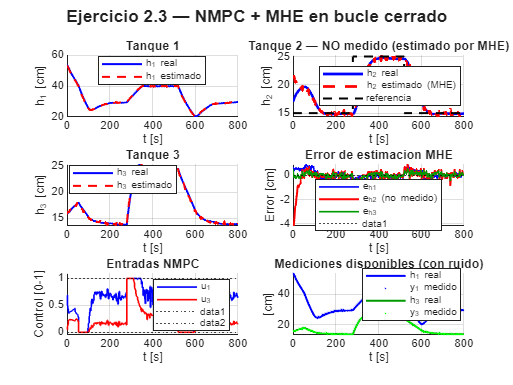


%% ============================
% 7. Graficas
% ============================
figure('Name','Ej 2.3 MHE + NMPC','Position',[50 50 1000 750]);

% h1
subplot(3,2,1); hold on; grid on;
plot(T_hist, X_true(1,:)*100,'b','LineWidth',1.5,'DisplayName','h_1 real');
plot(T_hist, X_est(1,:)*100, 'r--','LineWidth',1.5,'DisplayName','h_1 estimado');
ylabel('h_1 [cm]'); xlabel('t [s]'); title('Tanque 1');
legend('Location','best');

% h2 (no medido) + referencia
subplot(3,2,2); hold on; grid on;
plot(T_hist, X_true(2,:)*100,'b','LineWidth',2,'DisplayName','h_2 real');
plot(T_hist, X_est(2,:)*100, 'r--','LineWidth',2,'DisplayName','h_2 estimado (MHE)');
stairs(T_hist(1:end-1), yref_v*100,'k--','LineWidth',1.5,'DisplayName','referencia');
ylabel('h_2 [cm]'); xlabel('t [s]');
title('Tanque 2 — NO medido (estimado por MHE)');
legend('Location','best');

% h3
subplot(3,2,3); hold on; grid on;
plot(T_hist, X_true(3,:)*100,'b','LineWidth',1.5,'DisplayName','h_3 real');
plot(T_hist, X_est(3,:)*100, 'r--','LineWidth',1.5,'DisplayName','h_3 estimado');
ylabel('h_3 [cm]'); xlabel('t [s]'); title('Tanque 3');
legend('Location','best');

% Error de estimacion
subplot(3,2,4); hold on; grid on;
e1 = (X_true(1,1:Nsim)-X_est(1,1:Nsim))*100;
e2 = (X_true(2,1:Nsim)-X_est(2,1:Nsim))*100;
e3 = (X_true(3,1:Nsim)-X_est(3,1:Nsim))*100;
plot(T_hist(1:Nsim),e1,'b','LineWidth',1.2,'DisplayName','e_{h1}');
plot(T_hist(1:Nsim),e2,'r','LineWidth',1.5,'DisplayName','e_{h2} (no medido)');
plot(T_hist(1:Nsim),e3,'Color',[0 .6 0],'LineWidth',1.2,'DisplayName','e_{h3}');
yline(0,'k:'); ylabel('Error [cm]'); xlabel('t [s]');
title('Error de estimacion MHE');
legend('Location','best');

% Control
subplot(3,2,5); hold on; grid on;
stairs(T_hist(1:Nsim),U_hist(1,:),'b','LineWidth',1.2,'DisplayName','u_1');
stairs(T_hist(1:Nsim),U_hist(2,:),'r','LineWidth',1.2,'DisplayName','u_3');
yline(1,'k:'); yline(0,'k:');
ylabel('Control [0-1]'); xlabel('t [s]');
title('Entradas NMPC'); legend; ylim([-0.05 1.1]);

% Mediciones ruidosas
subplot(3,2,6); hold on; grid on;
plot(T_hist(1:Nsim),X_true(1,1:Nsim)*100,'b','LineWidth',1.5,'DisplayName','h_1 real');
plot(T_hist(1:Nsim),Y_hist(1,:)*100,'b.','MarkerSize',3,'DisplayName','y_1 medido');
plot(T_hist(1:Nsim),X_true(3,1:Nsim)*100,'Color',[0 .6 0],'LineWidth',1.5,'DisplayName','h_3 real');
plot(T_hist(1:Nsim),Y_hist(2,:)*100,'g.','MarkerSize',3,'DisplayName','y_3 medido');
ylabel('[cm]'); xlabel('t [s]');
title('Mediciones disponibles (con ruido)');
legend('Location','best');

sgtitle('Ejercicio 2.3 — NMPC + MHE en bucle cerrado','FontSize',13,'FontWeight','bold');


% Estadisticas
fprintf('\n=== Estadisticas (t > 400s) ===\n');


=== Estadisticas (t > 400s) ===


idx = T_hist(1:Nsim) > 400;
fprintf('  RMSE h1 = %.4f cm\n', sqrt(mean(e1(idx).^2)));

  RMSE h1 = 0.2679 cm


fprintf('  RMSE h2 = %.4f cm  (NO medido)\n', sqrt(mean(e2(idx).^2)));

  RMSE h2 = 0.2585 cm  (NO medido)


fprintf('  RMSE h3 = %.4f cm\n', sqrt(mean(e3(idx).^2)));

  RMSE h3 = 0.1710 cm



%% ================================================================
% FUNCIONES AUXILIARES
%% ================================================================

function w0 = make_warm_start_mpc(x0, u0, N, Ts, p, nx, nu, xmin, xmax)
    Xw = zeros(nx,N+1); Xw(:,1) = x0;
    for i = 1:N
        Xw(:,i+1) = max(xmin, min(xmax, rk4_m(Xw(:,i), u0, Ts, p)));
    end
    w0 = [reshape(Xw,nx*(N+1),1); repmat(u0,N,1)];
end

function xn = rk4_m(x, u, dt, p)
    k1 = nl_ode(x,          u, p);
    k2 = nl_ode(x+dt/2*k1, u, p);
    k3 = nl_ode(x+dt/2*k2, u, p);
    k4 = nl_ode(x+dt*k3,   u, p);
    xn = x + dt/6*(k1+2*k2+2*k3+k4);
end

function f = nl_ode(h, u, p)
    h1=max(0,h(1)); h2=max(0,h(2)); h3=max(0,h(3));
    qi1=p.qmax*u(1); qi3=p.qmax*u(2);
    qo1=p.alphao1*(p.Do1^2*pi/4)*sqrt(2*p.g*(h1+1e-10));
    qo2=p.alphao2*p.A2           *sqrt(2*p.g*(h2+1e-10));
    qo3=p.alphao3*(p.Do3^2*pi/4)*sqrt(2*p.g*(h3+1e-10));
    dh12=h1-h2;
    l12=p.D12*p.rho/p.eta*sqrt(2*p.g*abs(dh12)+1e-10);
    a12=p.alpha120*tanh(2*l12/p.lambdac12);
    q12=a12*p.A12*sqrt(2*p.g*abs(dh12)+1e-10)*sign(dh12+1e-15);
    dh23=h2-h3;
    l23=p.D23*p.rho/p.eta*sqrt(2*p.g*abs(dh23)+1e-10);
    a23=p.alpha230*tanh(2*l23/p.lambdac23);
    q23=a23*p.A23*sqrt(2*p.g*abs(dh23)+1e-10)*sign(dh23+1e-15);
    f=[(qi1-q12-qo1)/p.Atank;
       (q12-q23-qo2)/p.Atank;
       (qi3+q23-qo3)/p.Atank];
end